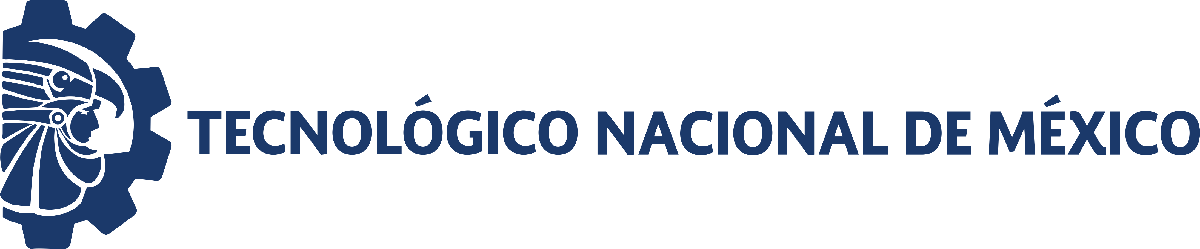                                 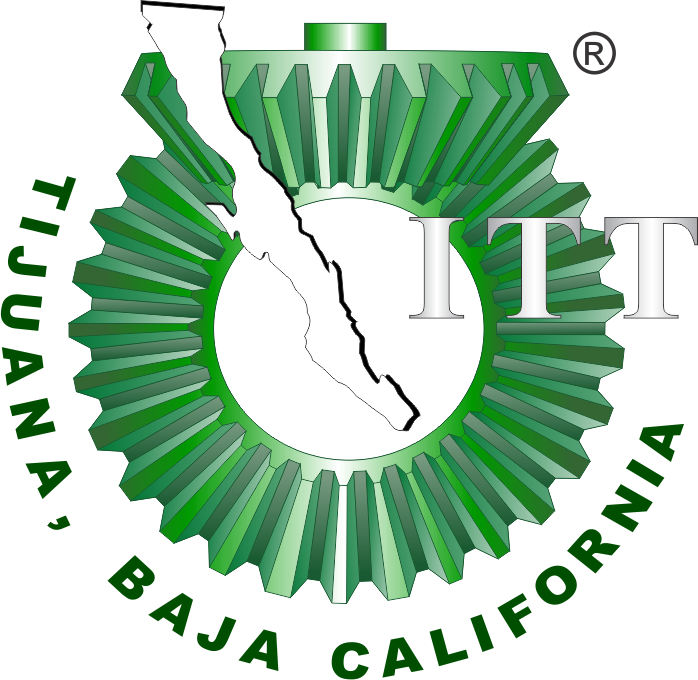

# Práctica 2: Sistema Respiratorio

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

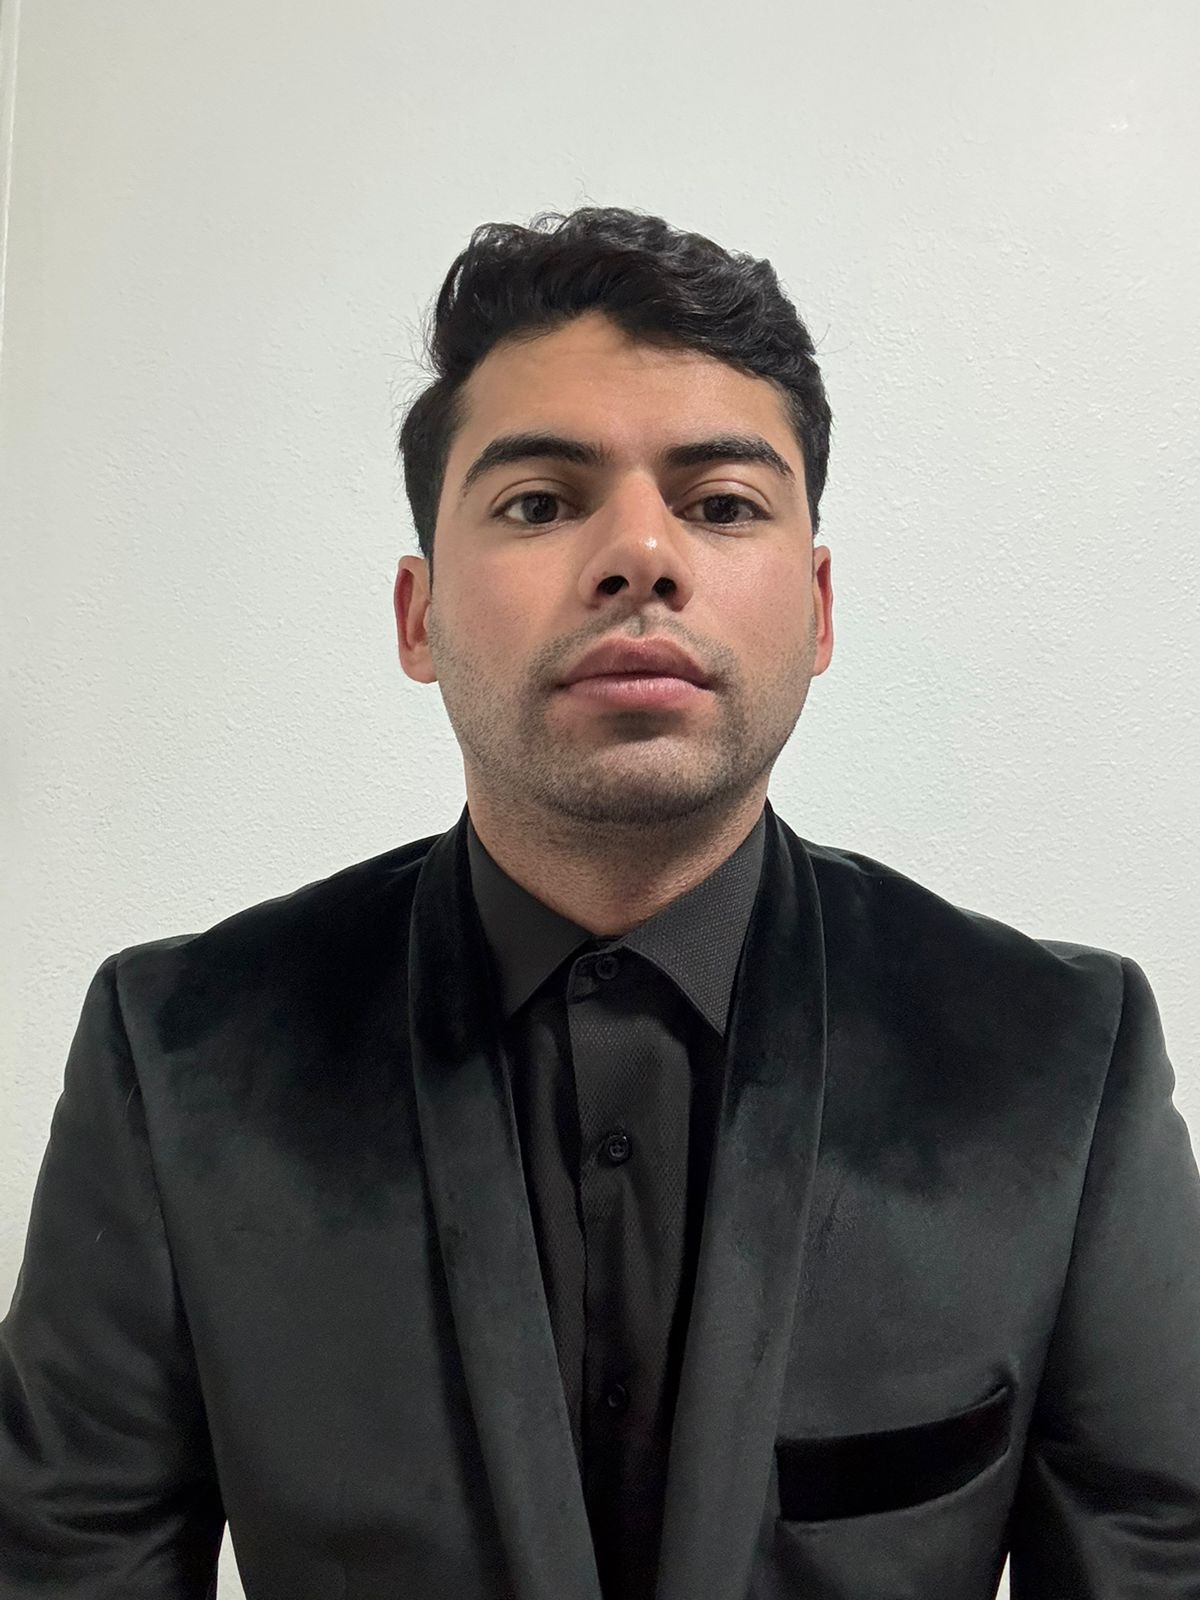

Nombre del alumno: **Perez Chavez Marco Antonio**

Número de control: **19212423**

Correo institucional: **marco.perez193@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

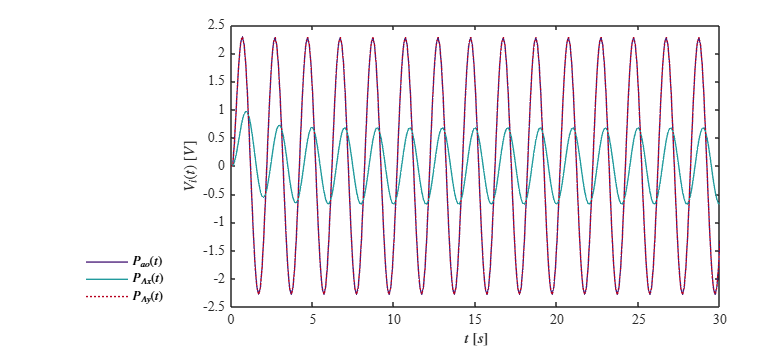

clc; clear; close all; warning('off','all')
file = 'Practica22';
open_system(file);
parameters.Stoptime = '30';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
Controlador = 'PID';

set_param('Practica22/PID Controller','P','254.794522788379');
set_param('Practica22/PID Controller','I','4952.03786900602');
set_param('Practica22/PID Controller','D','1.23977039590424');
set_param('Practica22/PID Controller','N','26057.2692515696');

Signal = 'Normal';
set_param('Practica22/Pao(t)','sw','0');
N = sim(file,parameters);
plotsignals(N.t,N.Pao,N.PAx,N.PAy,N.PAz,Signal)

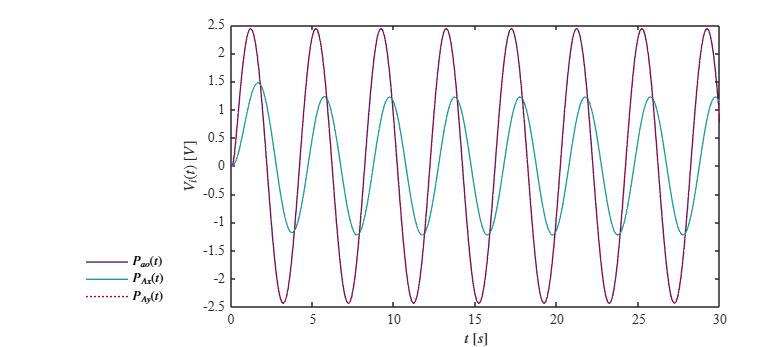


Signal = 'Anormal';
set_param('Practica22/Pao(t)','sw','1')
A = sim(file,parameters);
plotsignals(A.t,A.Pao,A.PAx,A.PAy,A.PAz,Signal)

## Rendimiento del controlador

kP=254.7945

kI=49520379

kD=1.23977

Setling time = 0.0878

Overshoot = 6.75%

## Función

function plotsignals(t,Pao,PAx,PAy,PAz,Signal)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,18,8])
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    
    nar = [1,128/255, 0];
    mor = [76/255, 31/255, 122/255];
    azu = [33/255, 155/255, 157/255];
    roj = [184/255, 0/255, 31/255];
    
    hold on; grid off; box on 

    %plot(t,Pao,'LineWidth',1,'Color',Morado)
    plot(t,PAx,'LineWidth',1,'Color',mor)
    plot(t,PAy,'LineWidth',1,'Color',azu)
    plot(t,PAz,':','LineWidth',1,'Color',roj)

    xlabel('$t$ $[s]$', 'Interpreter','Latex','FontSize',11)
    ylabel('$V_i(t)$ $[V]$', 'Interpreter','Latex','FontSize',11)
    
    L = legend('$P_{ao}(t)$','$P_{Ax}(t)$','$P_{Ay}(t)$','$P_{Az}(t)$');
    set(L,'Interpreter','Latex','Location','southwestoutside','Box','Off')

    if Signal == "Normal"
        xlim([0,30]); xticks(0:5:30)
        ylim([-2.5,2.5]); yticks(-2.5:0.5:2.5)
    elseif Signal == "Anormal"
        xlim([0,30]); xticks(0:5:30)
        ylim([-2.5,2.5]); yticks(-2.5:0.5:2.5)
    end
    
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')

end